clc; clear;
u = symunit;

CP = py.importlib.import_module("CoolProp.CoolProp")

CP =   Python module with properties:

                                  NORMALIZE_GAS_CONSTANTS: [1×1 py.int]
                                        SmassUmass_INPUTS: [1×1 py.int]
                                                PQ_INPUTS: [1×1 py.int]
                                                     iPIP: [1×1 py.int]
                                        irhomass_reducing: [1×1 py.int]
                                set_config_as_json_string: [1×1 py.builtin_function_or_method]
                             ASSUME_CRITICAL_POINT_STABLE: [1×1 py.int]
                                   USE_GUESSES_IN_PROPSSI: [1×1 py.int]
                                                  iUmolar: [1×1 py.int]
                                       PyGuessesStructure: [1×1 py.type]
                             get_mixture_binary_pair_data: [1×1 py.builtin_function_or_method]
                                     FLUID_TYPE_UNDEFINE

format longG

% Kølemiddel
ps = 100;
Tfrys = 0;
Tkog = 1200;
middel = "Water";

% for vand
Pmin = CP.PropsSI("P","T",274 - Tfrys,"Q",0,middel)

Pmin =           650.015609513709


Pmax = CP.PropsSI("P","T", 647,"Q",1,middel)

Pmax =           22038405.7269226


Plin = linspace(Pmin,Pmax, ps);


Hmin = CP.PropsSI("H","T",273.15,"Q",0,middel)

Hmin =          -41.5879599507678


Hmax = CP.PropsSI("H","T", 647,"Q",1,middel)

Hmax =           2148559.59458533


Hlin = linspace(Hmin, Hmax, ps);

Tny = zeros(1,ps);
Hny = zeros(1,ps);

for i = 1:ps
    Tny(i) = CP.PropsSI('T', 'P', Plin(i), 'Q', 0, middel);
end

min(Tny)

ans =           274.000000500733


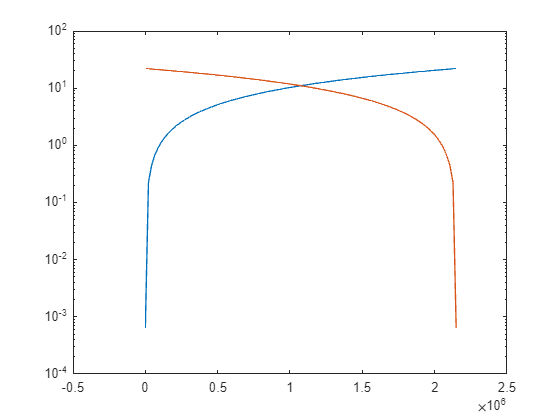



semilogy(Hlin,Plin/1e6)

hold on

semilogy(sort(Hlin,"descend"),Plin/1e6)

hold off

clc; clear all;

ps = 100

ps =    100


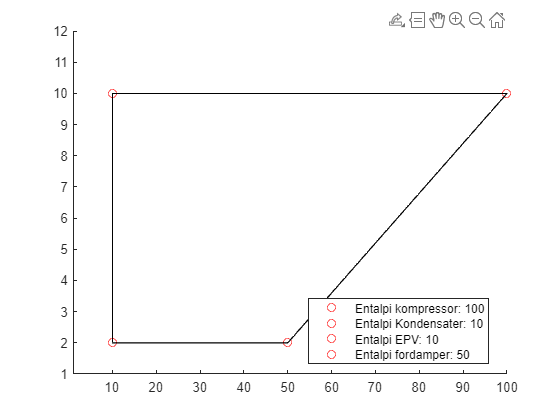

x1 = linspace(50,100,ps);
y1 = linspace(2,10,ps);

x2 = linspace(100,10,ps);
y2 = linspace(10,10,ps);

x3 = linspace(10,10,ps);
y3 = linspace(10,2,ps);

x4 = linspace(10,50,ps);
y4 = linspace(2,2,ps);

%plot(x1,y1,"k")



%plot(x1,y1,"k",x2,y2,"k",x3,y3,"k",x4,y4,"k")


for i = 1:ps
    scatter(x1(i),y1(i),"r")
    hold on

    xlim([1,100])
    ylim([1,12])




    scatter(x2(i),y2(i),"r")
    scatter(x3(i), y3(i),"r")
    scatter(x4(i),y4(i),"r")

    plot(x1,y1,"k",x2,y2,"k",x3,y3,"k",x4,y4,"k")

    legend("Entalpi kompressor: " + x1(i), "Entalpi Kondensater: " + x2(i), ...
        "Entalpi EPV: " + x3(i), "Entalpi fordamper: " + x4(i),"Location","best")

    drawnow

    pause(0.05)



    hold off
end

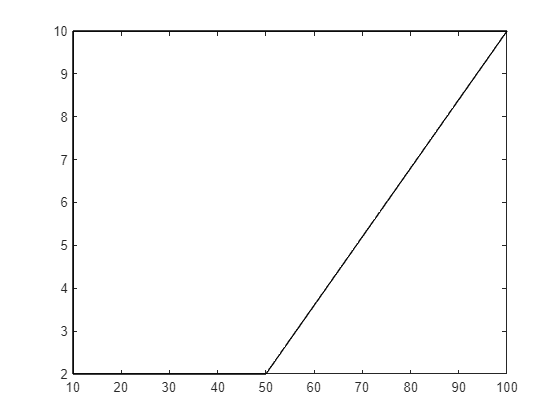

clear all;
ps = 100;
x1 = linspace(50,100,ps);
y1 = linspace(2,10,ps);

x2 = linspace(100,10,ps);
y2 = linspace(10,10,ps);

x3 = linspace(10,10,ps);
y3 = linspace(10,2,ps);

x4 = linspace(10,50,ps);
y4 = linspace(2,2,ps);



plot(x1,y1,"k",x2,y2,"k",x3,y3,"k",x4,y4,"k")